s=tf('s')


s =
 
  s
 
Continuous-time transfer function.


m=1;
k=1;
b=0.5;


A=[0,1;-k/m,-b/m];
B=[0;1/m];
C=[1,0];
D=0;

sys=ss(A,B,C,D)


sys =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -0.5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


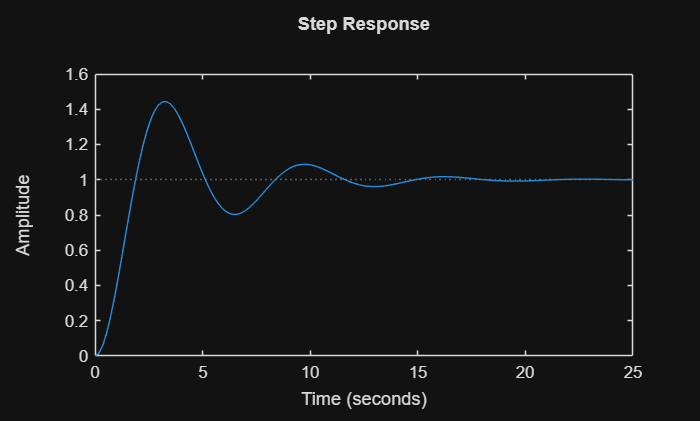

step(sys)

%initial(sys,[1,-5]')


R=0.5;
L=0.02;
J=0.5;
Km=0.43;
b=0.001;

A=[-R/L,-Km/L;Km/J,-b/J];
B=[1/L,0]';
C=[0,1];
D=0;

sys2=ss(A,B,C,D)


sys2 =
 
  A = 
           x1      x2
   x1     -25   -21.5
   x2    0.86  -0.002
 
  B = 
       u1
   x1  50
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


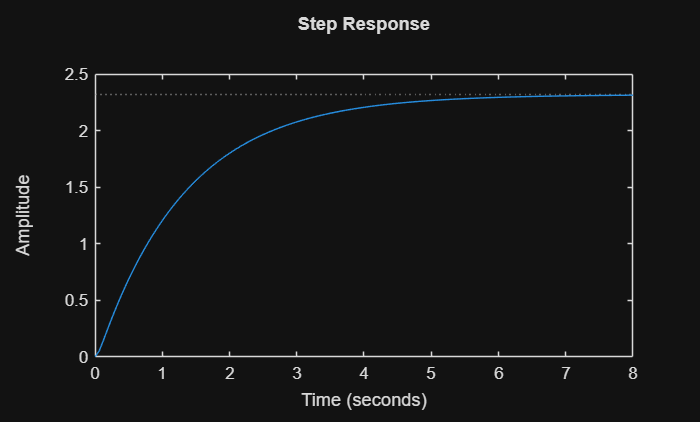

step(sys2)


A=[-R/L,0,-Km/L;
    0,0,1;
    Km/J,0,-b/J];
B=[1/L;0;0];
C=[0,1,0];
D=0;

sys3=ss(A,B,C,D)


sys3 =
 
  A = 
           x1      x2      x3
   x1     -25       0   -21.5
   x2       0       0       1
   x3    0.86       0  -0.002
 
  B = 
       u1
   x1  50
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


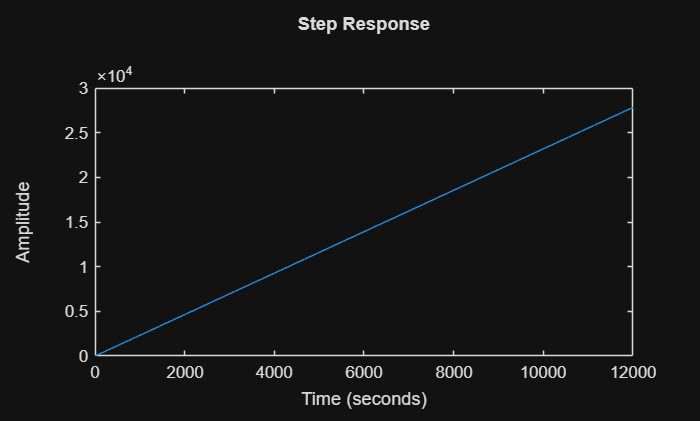

step(sys3)

A=[0,1;(-b*R+Km^2)/J*L,(-R*J+b*L)/J*L];
B=[0,k/(J*L)]';
C=[1,0];
D=0;

sys4=ss(A,B,C,D)


sys4 =
 
  A = 
              x1         x2
   x1          0          1
   x2   0.007376  -0.009999
 
  B = 
        u1
   x1    0
   x2  100
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


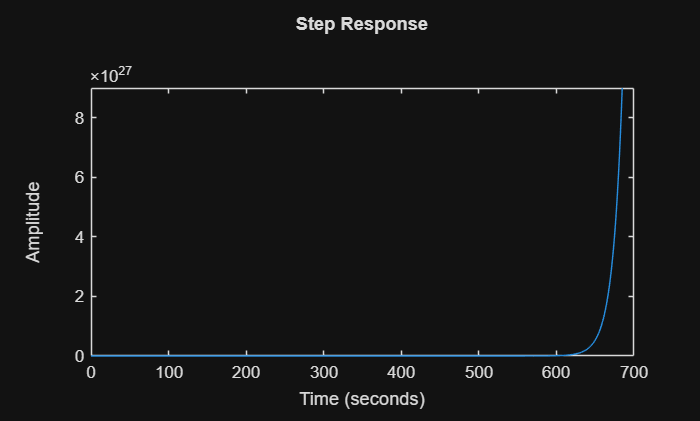

step(sys4)

m=1;
g=9.81;
l=1.5;
B=1.96;

A=[0,1;0,-g/l];
B=[0;1];
C=[1,0];
D=0;

sys5=ss(A,B,C,D)


sys5 =
 
  A = 
          x1     x2
   x1      0      1
   x2      0  -6.54
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


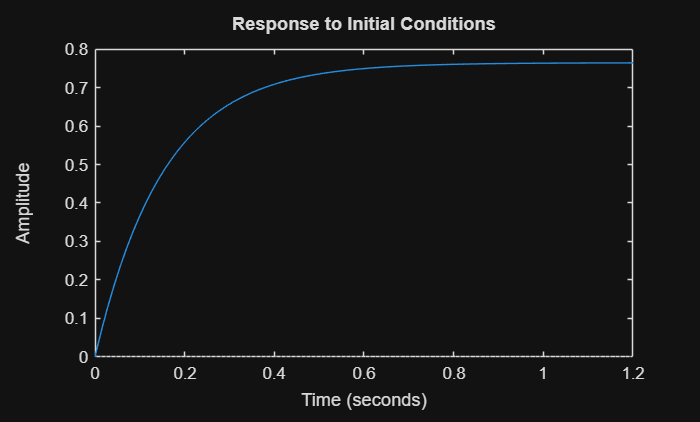


initial(sys5,[0,5])